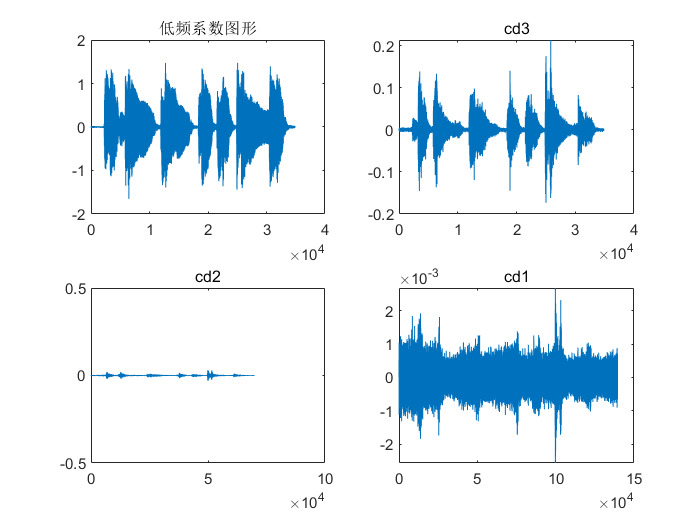

%加入白噪声的音频水印程序
clear;
[kk,fs] = audioread('ech7.wav');   %读入原始音频文件
%y=kk.wave;
y = kk(:,1); %双通道变单通道

[c,l]=wavedec(y,3,'db4');               %三级小波分解
ca3=appcoef(c,l,'db4',3);
cd3=detcoef(c,l,3);
cd2=detcoef(c,l,2);
cd1=detcoef(c,l,1);
x=ca3;                              %提取低频系数
len=length(y);
x1=x;
s=max(abs(x))*0.2;
i=find(abs(x)>s);
lx=length(x(i));         %找出大于最大值0.2倍的序列
figure;
subplot(2,2,1);
plot(ca3);                            %画出低频系数图
title('低频系数图形');
subplot(2,2,2);
plot(cd3);
title('cd3');
subplot(2,2,3);
plot(cd2);
axis([0 10e4 -0.5 0.5]);
title('cd2');
subplot(2,2,4);
plot(cd1);
title('cd1');

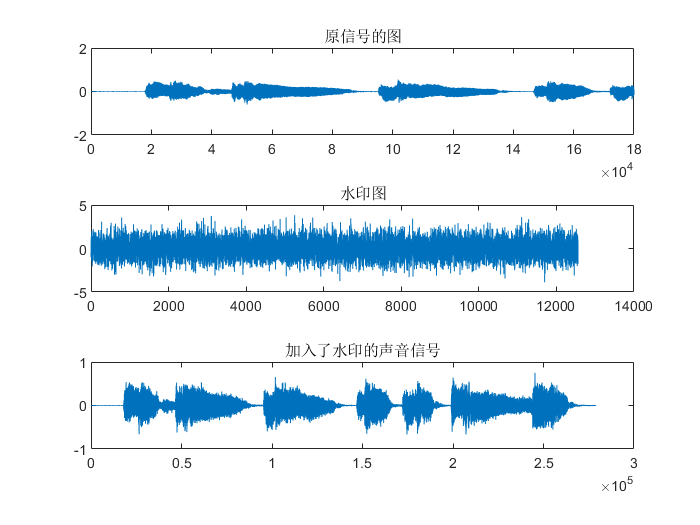


randn('seed',10);                      %产生随机高斯序列
mark=randn(1,lx);
ss=mark;
rr=ss*0.1;                           %设置水印嵌入强度
x(i)=x(i).*(1+2*rr');                   %嵌入水印
c1=[x',cd3',cd2',cd1'];
s1=waverec(c1,l,'db4');
file1='已加水印.wav';
dd=length(s1);                     %调整s1的长度,使之可以分成两列
s11=s1;                            %s1的值不能改变,因为后面还需要用到
if rem(dd,2)==1                    %如果s1是奇数,则去掉最后一个数,将新数组定义为s11
    s11=s1(1:dd-1);               
end
ee=reshape(s11,[],2);                %将s1调整成2列的数组
%audiowrite('z.wav',legend1,fs);
audiowrite('已加水印.wav',ee,fs);
figure;
subplot(3,1,1);plot(y);                   %画出原信号图
axis([0 18e4 -2 2]);
title('原信号的图');                    
subplot(3,1,2);plot(ss);
title('水印图');
subplot(3,1,3);plot(s1);                  %画出嵌入了水印的信号图
title('加入了水印的声音信号')

[kk,fs]= audioread(file1); 
yc=kk;
dy=length(y);
if rem(dy,2)==1                         %如果y为奇数,处理同s1,但是因为后面不需要用到y,所以不必定义一个新数组
    y=y(1:dd-1);
end
y1=reshape(y,[],2);                       %调整数组y的维数,使之可以和yc做运算
fz=sum(y1.*y1);                           %计算嵌入了水印的信号的信噪比,".*"用于实现对应元素的乘法
fm=sum((y1-yc).*(y1-yc));
SNR2=-10*log(fm/fz)

SNR2 = 33.1329

sound(yc,fs)